## 参数

L = frwlev(-[0.5, -0.5, 0.5, -0.5])

L =     1.0000         0         0         0         0
    0.5000    1.0000         0         0         0
   -0.5000    0.2500    1.0000         0         0
    0.5000   -0.3750         0    1.0000         0
   -0.5000    0.5000   -0.1875   -0.2500    1.0000


ar4 = L(end, end:-1:1)

ar4 =     1.0000   -0.2500   -0.1875    0.5000   -0.5000


ryy = rlev(ar4, 1)

ryy =     3.1605
   -1.5802
    1.9753
   -2.1728
    2.1975


scale = [7, 12, 10, 8, 6,] * ryy

scale = 18.7160


ryy =  ryy/scale

ryy =     0.1689
   -0.0844
    0.1055
   -0.1161
    0.1174


[L, E] = lev(ryy)

L =     1.0000         0         0         0         0
    0.5000    1.0000         0         0         0
   -0.5000    0.2500    1.0000         0         0
    0.5000   -0.3750   -0.0000    1.0000         0
   -0.5000    0.5000   -0.1875   -0.2500    1.0000


E =     0.1689    0.1266    0.0950    0.0712    0.0534


% diag(L*toeplitz(rxx)*L')
disp(ryy)

    0.1689
   -0.0844
    0.1055
   -0.1161
    0.1174



## 理论解

M = 6;
if length(ryy) < M+1
    ryy = [ryy' zeros(1, M + 1-length(E))]'
end

ryy =     0.1689
   -0.0844
    0.1055
   -0.1161
    0.1174
         0
         0



rxy = toeplitz(ryy)*[1 1 1 1 1 1 1]'

rxy =     0.1913
    0.1069
    0.2124
   -0.0211
    0.2124
    0.1069
    0.1913


[h,g,gamma] = firw(ryy, rxy);
disp(gamma')

   -0.5000    0.5000   -0.5000    0.5000    1.6358    0.9292



## 计算步长

Dlamb = eig(toeplitz(ryy))

Dlamb =    -0.0577
   -0.0010
    0.0674
    0.0922
    0.1577
    0.2172
    0.7062


mu = 1 /(sum(Dlamb)+ 2*max(Dlamb))/5;
disp([max(Dlamb) min(Dlamb) max(Dlamb)/min(Dlamb)])

    0.7062   -0.0577  -12.2457



disp(mu)

    0.0771



## 问b On the same graph

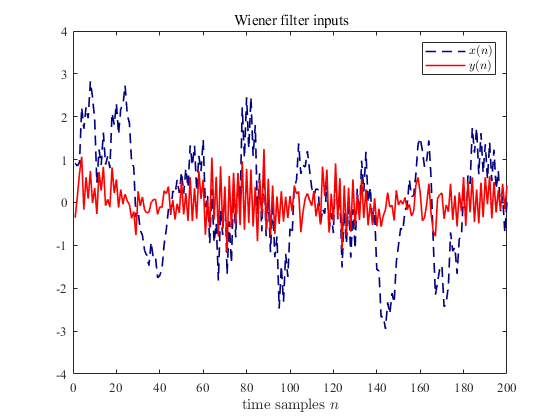

w = zeros(M+1,1);
h = w;
iteration = 200 + M;
us = sqrt(E(end) )*randn(iteration,1);
ys = filter(1,ar4,us);
signal = sin(0.075*pi*(1-M:iteration-M) + pi/2)';
xs = signal + filter(ones(1,M+1),1,ys);
ys = ys(M+1:end);
signal = signal(M+1:end);
xs = xs(M+1:end);

w0_rec = zeros(M+1,iteration-M);
error = zeros(iteration-M,1);
x_lms = zeros(iteration-M,1);
for i = 1:length(ys)
    y = ys(i);
    x = xs(i);
    [h,xhat,e,w] = lms(mu,h,w,x,y);
    error(i) = e;
    x_lms(i) = xhat;
    w0_rec(:,i) = h;
end
figure()
xrange = (1:iteration-M)';
plot(xrange, xs, 'Color', [0 0 0.5], "LineStyle","--", "LineWidth", 1.2)
hold on
plot(xrange, ys, 'r', "LineWidth", 1.2)
title('\rm Wiener filter inputs', "FontName", "Times New Roman")
xlabel( 'time samples $n$', 'Interpreter','Latex')
legend('$x(n)$', '$y(n)$', 'Interpreter','Latex')
ylim([-1 1]*4)
ax = gca;
set(gca, 'FontName', "Times New Roman")
% exportgraphics(ax,'input.png','Resolution',300)

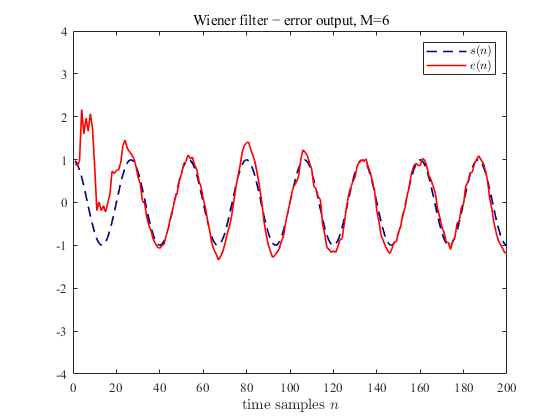


figure
plot(xrange, signal, 'Color', [0 0 0.5], "LineStyle","--", "LineWidth", 1.2)
hold on
plot(xrange, error, 'r', "LineWidth", 1.2)
title('\rm Wiener filter − error output, M=6', "FontName", "Times New Roman")
xlabel( 'time samples $n$', 'Interpreter','Latex')
legend('$s(n)$', '$e(n)$', 'Interpreter','Latex')
ylim([-1 1]*4)
ax = gca;
set(gca, 'FontName', "Times New Roman")
% exportgraphics(ax,'estimation error.png','Resolution',300)

## 问b Observe coefficient convergence

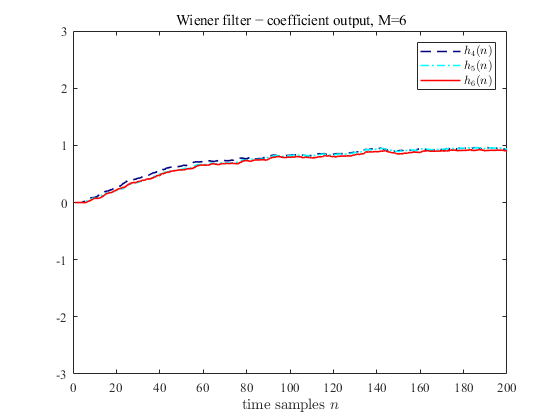

ensemble = 20;
iteration = 200 + M;
w0_rec = zeros(M+1,iteration-M);
error = zeros(iteration-M,1);
x_lms = zeros(iteration-M,1);

for j = 1:ensemble
    w = zeros(M+1,1);
    h = w;
    us = sqrt(E(end) )*randn(iteration,1);
    ys = filter(1,ar4,us);
    signal = sin(0.075*pi*(1-M:iteration-M) + pi/2)';
    xs = signal + filter(ones(1,M+1),1,ys);
    ys = ys(M+1:end);
    signal = signal(M+1:end);
    xs = xs(M+1:end);
    
    for i = 1:length(ys)
        y = ys(i);
        x = xs(i);
        [h,xhat,e,w] = lms(mu,h,w,x,y);
        error(i) = error(i) + e;
        x_lms(i) = x_lms(i) + xhat;
        w0_rec(:,i) = w0_rec(:,i) + h;
    end
end
error = error / ensemble;
x_lms = x_lms / ensemble;
w0_rec = w0_rec / ensemble;
xrange = (1:iteration-M)';

figure
plot(xrange, w0_rec(end-2,:), 'Color', [0 0 0.5], "LineStyle","--", "LineWidth", 1.2)
hold on
plot(xrange, w0_rec(end-1,:), 'c-.', "LineWidth", 1.2)
plot(xrange, w0_rec(end,:), 'r', "LineWidth", 1.2)

title('\rm Wiener filter − coefficient output, M=6', "FontName", "Times New Roman")
xlabel( 'time samples $n$', 'Interpreter','Latex')
legend('$h_4(n)$', '$h_5(n)$', '$h_6(n)$', 'Interpreter','Latex')
ylim([-1 1]*3)
ax = gca;
set(gca, 'FontName', "Times New Roman")
exportgraphics(ax,'coefficient avg.png','Resolution',300)

% disp(w0_rec(:, end))

## Change

L_change = frwlev(-[0.5, -0.5])

L_change =     1.0000         0         0
    0.5000    1.0000         0
   -0.5000    0.2500    1.0000


ar = L_change(end, end:-1:1)

ar =     1.0000    0.2500   -0.5000


ryy = rlev(ar, 1)

ryy =     1.7778
   -0.8889
    1.1111


scale = [4, 6, 4] * ryy

scale = 6.2222

ryy =  ryy/scale

ryy =     0.2857
   -0.1429
    0.1786


[L, E_change] = lev(ryy)

L =     1.0000         0         0
    0.5000    1.0000         0
   -0.5000    0.2500    1.0000


E_change =     0.2857    0.2143    0.1607



M = 6;
if length(ryy) < M+1
    ryy = [ryy' zeros(1, M + 1-length(E_change))]';
end

rxy = toeplitz(ryy)*[1 1 1 1 0 0 0]'

rxy =     0.3214
    0.1786
    0.1786
    0.3214
    0.0357
    0.1786
         0


[h,g,gamma] = firw(ryy, rxy)

h =     1.0000
    1.0000
    1.0000
    1.0000
    0.0000
   -0.0000
   -0.0000


g =     1.1250
    1.5833
    0.3889
    1.0000
   -0.0000
   -0.0000
   -0.0000


gamma =    -0.5000
    0.5000
    0.7222
   -0.2387
   -1.8898
    0.4253



Dlamb_change = eig(toeplitz(ryy))

Dlamb_change =    -0.0258
   -0.0137
    0.1457
    0.2188
    0.3094
    0.5466
    0.8190


mu_change = 1 /(sum(Dlamb_change)+ 2*max(Dlamb_change))/5;


## 问c Tracking the change with lms

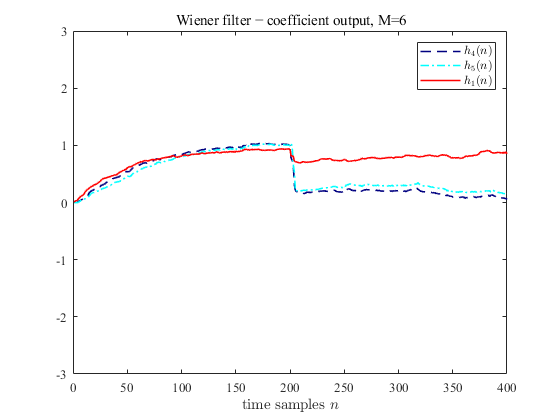

Ndata = 200;
ensemble = 30;
iteration = Ndata*2 + M;
w0_rec = zeros(M+1,iteration-M);
error = zeros(iteration-M,1);
x_lms = zeros(iteration-M,1);

for j = 1:ensemble
    w = zeros(M+1,1);
    h = w;
    us = sqrt(E(end) )*randn(Ndata+M,1);
    ys = filter(1,ar4,us);
    signal = sin(0.075*pi*(1-M:iteration-M) + pi/2)';
    xs = signal(1:Ndata+M) + filter(ones(1,M+1),1,ys);
    ys = ys(M+1:end);
    signal = signal(M+1:end);
    xs = xs(M+1:end);
    for i = 1:Ndata
        y = ys(i);
        x = xs(i);
        [h,xhat,e,w] = lms(mu,h,w,x,y);
        error(i) = error(i) + e;
        x_lms(i) = x_lms(i) + xhat;
        w0_rec(:,i) = w0_rec(:,i) + h;
    end
    
    %% need to modify back
    us = [us' sqrt(E_change(end)/100)*randn(1, Ndata)]';
    ys = [ys' filter(1,ar,us(Ndata+M+1:end), us(Ndata+M-1:Ndata+M))']';
    xs = [xs' signal(Ndata+1:end)' + filter(ones(1,4),1,ys(Ndata+1:end),ys(Ndata-2:Ndata))']';
    for i = Ndata+1:2*Ndata
        y = ys(i);
        x = xs(i);
        [h,xhat,e,w] = lms(mu*10,h,w,x,y);
        error(i) = error(i) + e;
        x_lms(i) = x_lms(i) + xhat;
        w0_rec(:,i) = w0_rec(:,i) + h;
    end
end
error = error / ensemble;
x_lms = x_lms / ensemble;
w0_rec = w0_rec / ensemble;
xrange = (1:iteration-M)';

figure
plot(xrange, w0_rec(end-2,:), 'Color', [0 0 0.5], "LineStyle","--", "LineWidth", 1.2)
hold on
plot(xrange, w0_rec(end-1,:), 'c-.', "LineWidth", 1.2)
plot(xrange, w0_rec(1,:), 'r', "LineWidth", 1.2)
title('\rm Wiener filter − coefficient output, M=6', "FontName", "Times New Roman")
xlabel( 'time samples $n$', 'Interpreter','Latex')
legend('$h_4(n)$', '$h_5(n)$', '$h_1(n)$', 'Interpreter','Latex')
ylim([-1 1]*3)
ax = gca;
set(gca, 'FontName', "Times New Roman")
% exportgraphics(ax,'coefficient avg tracking per100100.png','Resolution',300)

disp(w0_rec(:, end))

    0.8553
    0.8807
    0.4675
    0.5380
    0.0510
    0.1558
    0.0520



## 问c Tracking the change with rlsl

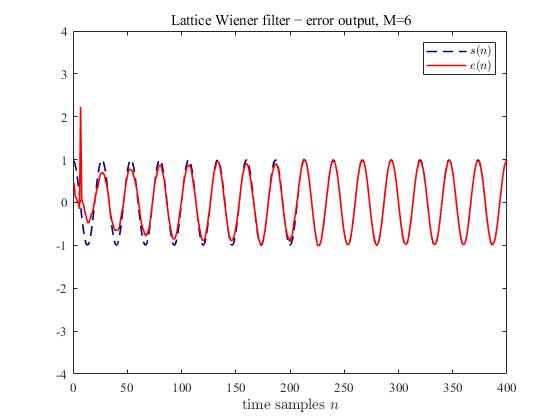

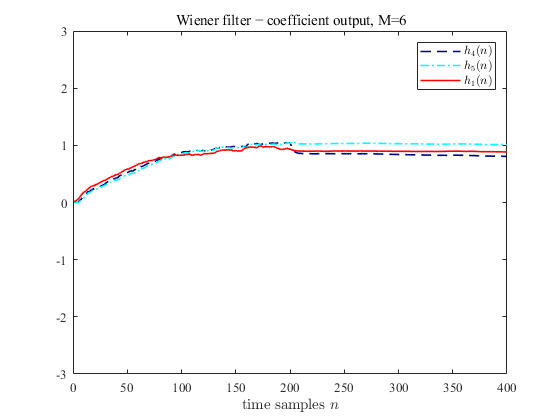

    0.8830
    1.0038
    0.8911
    0.9593
    0.8039
    1.0096
    0.7281



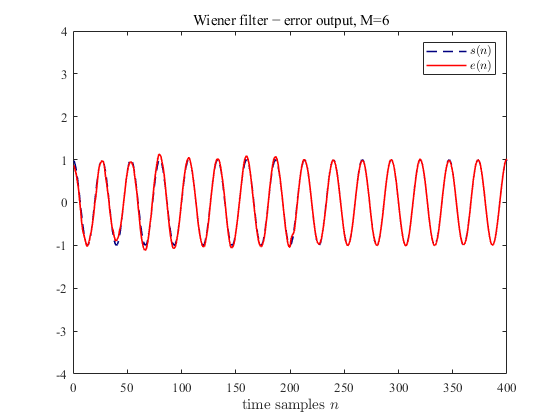

Ndata = 200;
iteration = Ndata*2 + M;
error = zeros(iteration-M,1);
x_lms = zeros(iteration-M,1);

for j = 1:ensemble
    w0 = zeros(M,1);
    w1 = zeros(M,1);
    g = zeros(M+1,1);
    ga = zeros(M,1);
    gb = ga;
    D1a = 0.01*ones(M+1,1);
    D = D1a;
    lambda = 0.99;
    
    us = sqrt(E(end) )*randn(Ndata+M,1);
    ys = filter(1,ar4,us);
    signal = sin(0.075*pi*(1-M:iteration-M) + pi/2)';
    xs = signal(1:Ndata+M) + filter(ones(1,M+1),1,ys);
    ys = ys(M+1:end);
    signal = signal(M+1:end);
    xs = xs(M+1:end);
    for i = 1:Ndata
        y = ys(i);
        x = xs(i);
        [xhat,e,w0,w1,g,ga,gb,D1a,D] = rlsl(x,y,w0,w1,g,ga,gb,D1a,D,lambda);
        error(i) = error(i) + e;
        x_lms(i) = x_lms(i) + xhat;
    end
    
    %% need to modify back
    us = [us' sqrt(E_change(end) )*randn(1, Ndata)]';
    ys = [ys' filter(1,ar,us(Ndata+M+1:end), us(Ndata+M-1:Ndata+M))']';
    xs = [xs' signal(Ndata+1:end)' + filter(ones(1,4),1,ys(Ndata+1:end),ys(Ndata-2:Ndata))']';
    for i = Ndata+1:2*Ndata
        y = ys(i);
        x = xs(i);
        [xhat,e,w0,w1,g,ga,gb,D1a,D] = rlsl(x,y,w0,w1,g,ga,gb,D1a,D,lambda);
        error(i) = error(i) + e;
        x_lms(i) = x_lms(i) + xhat;
    end
end
error = error / ensemble;
x_lms = x_lms / ensemble;
xrange = (1:iteration-M)';

figure
plot(xrange, signal, 'Color', [0 0 0.5], "LineStyle","--", "LineWidth", 1.2)
hold on
plot(xrange, error, 'r', "LineWidth", 1.2)
title('\rm Lattice Wiener filter − error output, M=6', "FontName", "Times New Roman")
xlabel( 'time samples $n$', 'Interpreter','Latex')
legend('$s(n)$', '$e(n)$', 'Interpreter','Latex')
ylim([-1 1]*4)
ax = gca;
set(gca, 'FontName', "Times New Roman")
% exportgraphics(ax,'estimation error tracking rlsl.png','Resolution',300)